# Optimierung für Industrielogistiker

## Übungsaufgabe 1

Programmieren Sie die Goldener-Schnitt-Suche aus dem Skriptum aus. Benützen Sie dafür den unten stehenden Code.

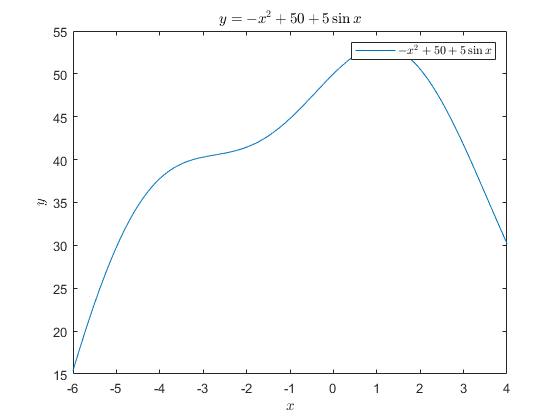

clear variables;
clc;
addpath('HelperFunctions\');

FINDMAXIMUM = true;

f = @(x) -x.^2 + 50 + 5 * sin(x);
X_U = -6;
X_O = 4;
x = linspace(X_U, X_O, 1000000);
y = f(x);
plot(x, y);
title('$y = -x^2 + 50 + 5 \sin x$', 'interpreter', 'latex');
xlabel('$x$', 'interpreter', 'latex');
ylabel('$y$', 'interpreter', 'latex');
legend('$-x^2 + 50 + 5 \sin x$', 'interpreter', 'latex');

MAX_NUMBER_OF_ITERATIONS = 100000000;
EPSILON = 1e-8;
x = goldensectionsearch(f, X_U, X_O, EPSILON, MAX_NUMBER_OF_ITERATIONS);
disp(['x = ', num2str(x, '%.8f')]);

x = 4.00000000
